clc;clear;

Ts=0.4713;Tr=0.1044;a=0.0005;g=atand(1/3);ks=1.29e-7*100*3600;q=2.85e-6*100*3600/ks;Fae=0;
% A=3.032e-8;B=-1.172e-4;C=0.3269;
A=0;B=0;C=0.34;
H=1*100*a*cosd(g);
bm=load('bm18.txt'); 
bn=load('bn18.txt');

tic
tp1=5.27; % the runoff time(hour)
tp=tp1*ks*a*cosd(g)^2/(Ts-Tr);
ZJ=20;ZT=24-ceil(tp1);
k=zeros(ZT+1,ZJ);
f=zeros(ZT+1,ZJ);
p=zeros(ZT+1,ZJ);
T=zeros(ZT+1,ZJ);

parfor i=0:ZT
    tt(i+1)=i+(ceil(tp1)-tp1);
    t=ks*a*tt(i+1)*cosd(g)^2/(Ts-Tr);    
for j=1:ZJ
    z=(j-1)/ZJ*H;
    W=0;
for n=1:1999
    Fn=0;
    for m=1:1999
    Dm=(4*bm(m)+(3-4*bm(m)^2)*exp(H/2)*sin(bm(m)*H))/(1+4*bm(m)^2);
    Em=(16*bm(m)*(2*cos(bm(m)*H)*exp(H/2)-1)/(1+4*bm(m)^2)+(3-4*bm(m)^2)*exp(H/2)*H*sin(bm(m)*H))/(1+4*bm(m)^2);
    Fm=(C-Tr)*sin(bm(m)*H)*exp(H/2)/(Ts-Tr)+B*(sin(bm(m)*H)*H*exp(H/2)-Dm)/(a*cosd(g)*(Ts-Tr))+A*(sin(bm(m)*H)*H^2*exp(H/2)-2*Em)/(a^2*cosd(g)^2*(Ts-Tr));

    E1=2*((0.25+bm(m)^2)*exp(-bm(m)^2*tp-tp/4)*Fm+q*exp(H/2)*(bm(m)*cos(bm(m)*H)+0.5*sin(bm(m)*H))*(1-exp(-bm(m)^2*tp-tp/4)))/((H*(bm(m)^2+0.25)+1)*(0.25+bm(m)^2));
    Fn=Fn+((bm(m)*sin(bn(n)*H)-bn(n)*sin(bm(m)*H))/(2*(bm(m)^2-bn(n)^2))-bm(m)*bn(n)*(cos(bm(m)*H)-cos(bn(n)*H))/(bm(m)^2-bn(n)^2))*E1;
    end  
    
    W=W+2*sin(bn(n)*(H-z))*((bn(n)^2+0.25)*Fn*exp(-bn(n)^2*t)+exp(H/2)*bn(n)*(exp(t*0.25)-exp(-bn(n)^2*t)))/(H*(bn(n)^2+0.25)+0.5);

end
    k(i+1,j)=W*exp(-0.5*z-0.25*t);
    f(i+1,j)=(log(k(i+1,j))/a-Fae*100)/100;
    p(i+1,j)=k(i+1,j)*ks/100/3600;
    if W*exp(-0.5*z-0.25*t)*(Ts-Tr)+Tr<Ts
        T(i+1,j)=W*exp(-0.5*z-0.25*t)*(Ts-Tr)+Tr;
    else
        T(i+1,j)=Ts;
    end
end
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 2 3 4 5 7 8 10 13 14 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 12 workers.

bn =

   1.0e+05 *

   0.000334305790000
   0.000994518720000
   0.001656401080000
   0.002318525230000
   0.002980730120000
   0.003642971710000
   0.004305233090000
   0.004967506330000
   0.005629787250000
   0.006292073430000
   0.006954363360000
   0.007616656060000
   0.008278950880000
   0.008941247330000
   0.009603545080000
   0.010265843890000
   0.010928143550000
   0.011590443920000
   0.012252744890000
   0.012915046360000
   0.013577348270000
   0.014239650540000
   0.014901953130000
   0.015564256010000
   0.016226559130000
   0.016888862470000
   0.017551165990000
   0.018213469690000
   0.018875773550000
   0.019538077540000

toc

历时 30.666996 秒。


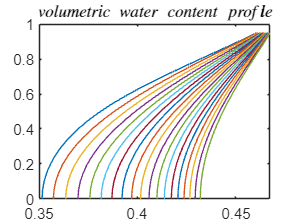

for j=1:ZJ
z(j)=(j-1)/ZJ*H/a/100/cosd(g);
end
for i=0:1:ZT
x(i+1,:)=T(i+1,:);
y2=z(1,:);
plot(x(i+1,:),y2)
title('$volumetric \ water \ content \ profile$','Interpreter','latex')
hold on;
end
hold off;

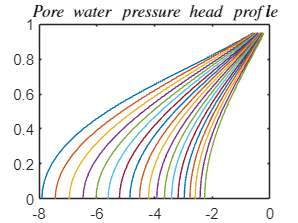

for i=0:1:ZT
x1(i+1,:)=f(i+1,:);
y=z(1,:);
plot(x1(i+1,:),y)
title('$Pore \ water \ pressure \ head \ profile$','Interpreter','latex');
hold on;
end
hold off;

for i=1:ZT+1
    x2(i,:)=(-f(i,19)/0.1+cosd(g))*ks*10/1000/3600;    
    x3(i,:)=sum(x2(1:i))*1000*3600;
end
t1=1:ZT+1

t1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19


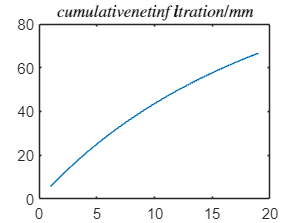

plot(t1,x3)
title('$cumulative net infiltration/mm$','Interpreter','latex')

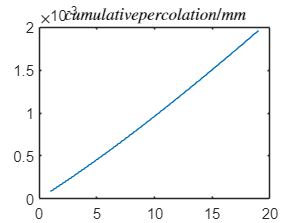


for i=0:ZT
p1(i+1,1)=p(i+1,1);
p2(i+1,1)=sum(p1(1:i+1,1))*1000;
end
plot(t1,p2)
title('$cumulative percolation/mm$','Interpreter','latex')
hold off;

c=5.74;f1=26.6;fb=14.1;rd=14.2;rw=9.81;H1=1.0;
uw=f*9.81;
g1=T*0.01*rw;
for i=1:ZT+1
    for j=1:100
        z(j)=(j-1)/100*H1;
        g2=g1(i,:);
        FOS(i,j)=(c-uw(i,j)*tand(fb))/((rd*(H1-z(j))+sum(g2(j:100)))*tand(g))+tand(f1)/tand(g);        
    end
end

索引超过数组元素的数量。索引不能超过 20。

for i=1:ZT+1
x4(i,:)=FOS(i,:);
y=z(1,:);
plot(x4(i,:),y)
ylim([0 0.8])
hold on;
end
title('$FOS$','Interpreter','latex')